# Microtest 2020

clc
clear
close all

T = readtable('y_icu_sept_bis.txt','delimiter', '\t', 'ReadVariableNames', true);

t = (T.t(:));
y = (T.y(:));

## 
$$ $y_t = \beta_1t +\beta_0$$$


## Question 1

Quelle est la taille des données ?

taille = length(y)

taille =     73


## Question 2a

Quelle est l'estimation de $$\beta_1$$� (la pente) de la régression linéaire ?

% p=polyfit(t,y,1);
% plot(t,y)
% hold
% plot(t,p(1)*t+p(2))
% beta1 = p(1)
% beta0 = p(2);

mdl = fitlm(t,y)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                        Estimate                 SE                  tStat                 pValue       
                   __________________    ___________________    ________________    ____________________

    (Intercept)      5.70050694709589     0.0432638069020242    131.761565966799    1.34088423382357e-86
    x1             0.0458725191751204    0.00101607514880961    45.1467780004879    4.95758524694971e-54


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 0.183
R-squared: 0.966,  Adjusted R-Squared: 0.966
F-statistic vs. constant model: 2.04e+03, p-value = 4.96e-54

beta1 = mdl.Coefficients.Estimate(2)

beta1 =    0.045872519175120


beta0 = mdl.Coefficients.Estimate(1);


## Question 2b

En combien de jours le nombre d'admissions journalières en réanimation $$h_t$$ est multiplié par deux ?

h = zeros(taille,1);
for i=1:(taille)
    h(i) = 2^(beta0) * 2^(beta1*(i));
end

x = h(2);
days = 2;
while(x <= 2*h(1))
    days = days + 1;
    x = h(days);
end
days = days-1

days =     22


## Question 3

Que vaut le $$R^2$$ (non ajusté) ?

Rcarre = mdl.Rsquared.Ordinary

Rcarre =    0.966338451776625


## Question 4

On en conclut que l'adéquation de $$y_t$$ à une droite est bonne ou mauvaise ?

figure
plot(t,y)
hold

Current plot held


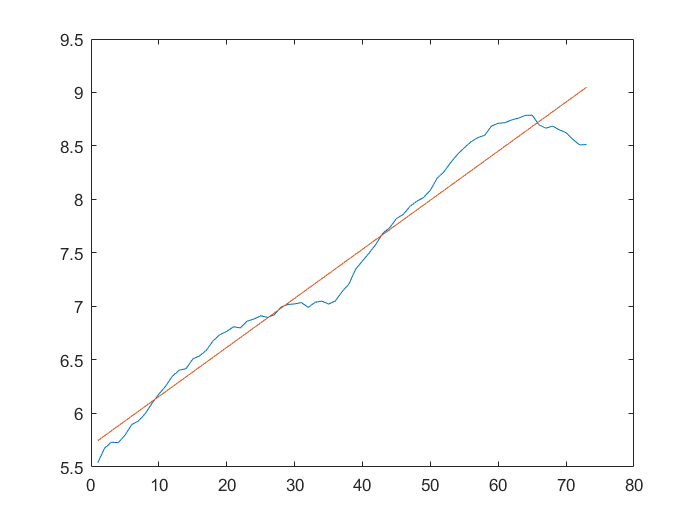

plot(t,log2(h(t)))

Oui.

## Question 5a

module_t = mdl.Coefficients.tStat(2)

module_t =   45.146778000487913


## Question 5b

liberte = mdl.DFE

liberte =     71


## Question 5c

## Question 6

ESS = mdl.SSE

ESS =    2.375832604166966


## Question 7

ecart_type = mdl.RMSE

ecart_type =    0.182927392821904
